## 3d : 

%%%%%%%%% INIT %%%%%%%%%%
v = 0.01;
N = 3;

%% Discretisation
h=1/(N+1);
dt = 1;
[Y,X,Z]=meshgrid(0:h:1,0:h:1,0:h:1);
X=reshape(X,[(N+2)^3,1]);
Y=reshape(Y,[(N+2)^3,1]);
Z=reshape(Y,[(N+2)^3,1]);
%% Création des matrices intermédiaire 
A1= v*-(1/h^2)*Laplace3d(N+2,N+2,N+2);
A = kron(eye(3),A1);

%La matrice B1 (resp. B2, B3) correspond à la dérivée par rapport à x (resp. y,z) de la pression.

B_1 = spdiags([ones( (N+1),1),-ones((N+1),1)], [0,-1], (N+1), (N+2));
B_2 = spdiags([-ones( (N+1),1),-ones((N+1),1)], [0,-1], (N+1), (N+2));
B_3 = spdiags([ones( (N+1),1),ones((N+1),1)], [0,-1], (N+1), (N+2));

B_ = spdiags([ones((N+1),1),ones((N+1),1),ones((N+1),1),ones((N+1),1)], [0,-1,-3,-4], (N+2), (N+1));

B1 = kron(B_3,kron(B_3,B_1));
B2 = kron(B_2,kron(B_1,B_2));
B3 = kron(B_1,kron(B_3,-B_2));
f1 = zeros((N+2)^3,1);
f2 = -30 * ones((N+2)^3,1);
f3 = zeros((N+2)^3,1);
Zb = zeros((N+1)^3,1);

%%%%%%%%%%Penalisation

I1 = eye(N+2);
I2 = zeros(N+2);
I2(1,1) = 1;
I2(end, end)=1;
I3 = kron(I2,I1) + kron(eye(N+2),I2) - kron(I2,I2);
I_ = kron(eye(N+2),I3);
eps = 10^(7); 

u_temp1 = zeros( (N+2),1);
u_temp1(end,1) = 1;             %forme de la mat bloc (0 partout sauf pour le bloc du bord du haut)
u_temp2 = ones((N+2),1); 
u_temp1= kron( u_temp1, u_temp2); 
u_temp1 = kron(u_temp1, u_temp2);
ubord1 =  15*u_temp1;
%ubord2 = zeros((N+2)^2,1);


%% Assemblage
M = [A1+eps*I_,zeros( (N+2)^3),zeros( (N+2)^3),B1.';
    zeros( (N+2)^3), A1+eps*I_,zeros( (N+2)^3), B2.';
    zeros( (N+2)^3),zeros( (N+2)^3),A1+eps*I_,B3.';
    B1, B2,B3, zeros((N+1)^3) ];
b = [f1+eps*ubord1;f2;f3;Zb];

tmp = M\b;
u1 = tmp(1:(N+2)^3,1);
u2 = tmp(1+(N+2)^3:2*(N+2)^3,1);
u3 = tmp(1+2*(N+2)^3:3*(N+2)^3,1);

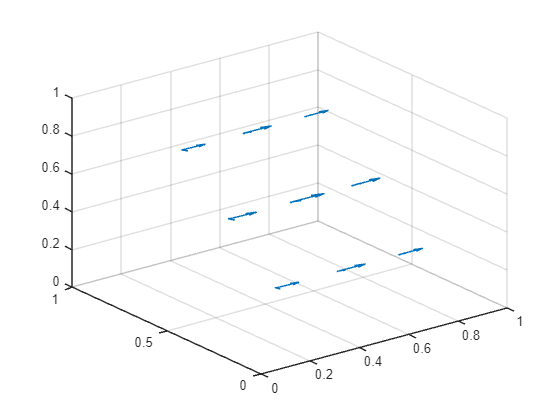

%%%%%%%%% PLOT
quiver3(X,Y,Z,u1,u2,u3)

p = tmp(1+3*(N+2)^3:end,1);

p = reshape(p,4,4,4)

p = p(:,:,1) =

   1.0e+06 *

   -0.4251    3.2248    1.5097    2.8964
    3.1717   -0.6818    0.8637   -1.1949
   -0.1870    2.0990    1.3830    2.3022
    0.9643    0.0651    0.2882   -0.2724


p(:,:,2) =

   1.0e+06 *

    3.7152    0.1376    0.7746   -1.9396
    0.0935    3.0958    1.4493    3.3163
    2.4176   -0.2731    0.4846   -0.9817
    0.1954    1.2113    1.0245    1.3247


p(:,:,3) =

   1.0e+06 *

   -0.1701    6.3647    5.7913    7.1938
    5.7107   -0.1533    1.6112   -1.7574
    0.1178    3.6919    2.8663    3.9157
    1.2564   -0.2101    0.0892   -0.4999


p(:,:,4) =

   1.0e+07 *

    0.8430   -0.3387    0.2178   -0.4266
   -0.4644    1.1365    1.0382    1.5082
    0.3304    0.0792    0.2288    0.0036
    0.0480   -0.0631   -0.1447   -0.1300


h_=1/(N)

h_ = 0.3333

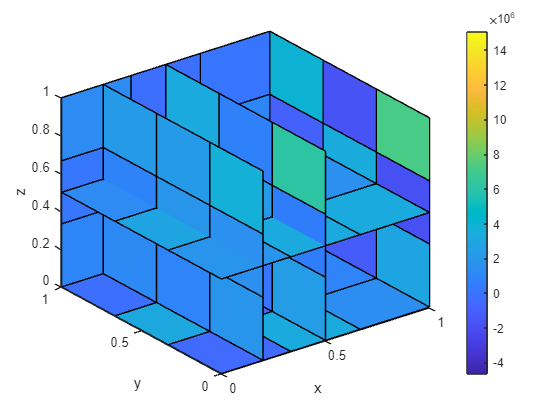

[X,Y,Z]=meshgrid(0:h_:1,0:h_:1,0:h_:1);
xslice = [0.2,.5,1];    % location of y-z planes
yslice = 1;              % location of x-z plane
zslice = [0,0.5];         % location of x-y planes

slice(X,Y,Z,p,xslice,yslice,zslice)
xlabel('x')
ylabel('y')
zlabel('z')
colorbar()

## Annexes :

#### Fonction : 

function [M] = Laplace1d(n)
    e = ones(n, 1);
    M = spdiags([e -2*e e], -1:1, n, n);
end

function [M] = Laplace2d(n1, n2)
    M = kron(speye(n2), Laplace1d(n1)) + kron(Laplace1d(n2), speye(n1));
end

function [M] = Laplace3d(n1, n2, n3)
    M = kron(kron(speye(n3), speye(n2)), Laplace1d(n1)) ...
    + kron(kron(speye(n3), Laplace1d(n2)), speye(n1)) ...
    + kron(kron(Laplace1d(n3), speye(n2)), speye(n1));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [x,y] = Schur(M,F,n,y,nmax,epsilon)

    A = M(1:2*(n+2)^2,1:2*(n+2)^2);
    B = M(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2,1:2*(n+2)^2);
    Bt = M(1:2*(n+2)^2,2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);
    C = M(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2,2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);
    c = F(1:2*(n+2)^2);
    d = F(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);

    x=A\(c-Bt*y);
    r=d-C*y-B*x;
    dd=r;
    k=0;

    while (k<nmax) && (norm(M*cat(1,x,y)-F) > epsilon)
        w=A\(Bt*dd);
        z=C*dd-B*w;
        alpha=dot(r,dd)/dot(dd,z);
        y=y+alpha*dd;
        x=x-alpha*w;
        rr=r;
        r=r-alpha*z;
        beta=dot(r,r)/dot(rr,rr);
        dd=r+beta*dd;
        k=k+1;
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [x,y] = Schur_Bloc(M,F,n,y,nmax,epsilon)
    
    A1 = M(1:(n+2)^2,1:(n+2)^2);
    A2 = M(1+(n+2)^2:2*(n+2)^2,1+(n+2)^2:2*(n+2)^2);

    B1 = M(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2,1:(n+2)^2);
    B2 = M(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2,1+(n+2)^2:2*(n+2)^2);
    B1t = M(1:(n+2)^2,2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);
    B2t = M(1+(n+2)^2:2*(n+2)^2,2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);

    f1 = F(1:(n+2)^2);
    f2 = F((n+2)^2+1:2*(n+2)^2);
    %f3 = F(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);

    u1 = A1\(f1-B1t*y);
    u2 = A2\(f2-B2t*y);
    
    r=B1*u1+B2*u2;
    dd=r;
    k=0;

    while (k<nmax) && (norm(M*vertcat([u1;u2],y)-F) > epsilon)
        w1=A1\(B2t*dd);
        w2=A2\(B2t*dd);
        z=B1*w1+B2*w2;
        alpha=dot(r,dd)/dot(dd,z);
        y=y+alpha*dd;
        u1=u1-alpha*w1;
        u2=u2-alpha*w2;
        rr=r;
        r=r-alpha*z;
        beta=dot(r,r)/dot(rr,rr);
        dd=r+beta*dd;
        k=k+1;
    end
    x = [u1;u2];
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [x,y] = Schur_Approx(M,F,n,y,nmax,epsilon,Precond)

    A = M(1:2*(n+2)^2,1:2*(n+2)^2);
    B = M(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2,1:2*(n+2)^2);
    Bt = M(1:2*(n+2)^2,2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);
    C = M(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2,2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);
    c = F(1:2*(n+2)^2);
    d = F(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);

    %x=A\(c-Bt*y);
    x0 = rand(2*(n+2)^2,1);
    x = GCP(A,x0,(c-Bt*y),Precond);

    r=d-C*y-B*x;
    dd=r;
    k=0;

    while (k<nmax) && (norm(M*cat(1,x,y)-F) > epsilon)
        %w=A\(Bt*dd);
        w = GCP(A,x0,(Bt*dd),Precond);
        z=C*dd-B*w;
        alpha=dot(r,dd)/dot(dd,z);
        y=y+alpha*dd;
        x=x-alpha*w;
        rr=r;
        r=r-alpha*z;
        beta=dot(r,r)/dot(rr,rr);
        dd=r+beta*dd;
        k=k+1;
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [sol] = GCP(A, x, b, Precond)
    tol = 10e-6;
    err = tol + 1;
    nb_iter = 0;
    r = b - A * x;
    z = Precond(A, r, true);
    d = z;
    
    res = [];
    iter = 0;
    while (err > tol)&&(nb_iter<10) %On met 10 iteration max
        xsave = x;
        rsave = r;
        zsave = z;
        
        alpha = dot(r, d) / dot(A * d, d);
        x = x + alpha * d;
        r = r - alpha * A * d;

        z = Precond(A, r, false);
        res = [res, r];
        beta = dot(r, z) / dot(rsave, zsave);
        d = z + beta * d;
        
        err = norm(xsave - x) / norm(xsave);
        nb_iter= nb_iter + 1;
        iter=iter +1;
    end
    sol = x;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Les fonctions suivante se trouvait dans des fichiers/scripts séparer lors
% de la compilation du notebook il se peut qu'il y faille les remettres
% dans des scripts séparer si lors d'une recompilation il y a des problèmes
% recontrés.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function z = Precond_SSOR(A, r, premier_passage)
    global L_SSOR U_SSOR D
    
    if premier_passage
        % On ne veut calculer la décomposition ILU qu'une fois : lors du premier passage.
        [L_SSOR, U_SSOR, D] = init_ssor(A);
    end
    z = U_SSOR \ (D * (L_SSOR \ r));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [L, U, D] = init_ssor(A)
    D = diag(diag(A));
    L = tril(A, -1);
    U = triu(A, 1);
    w_opt = 1.7; % recommendation du prof.
    
    L = (D + w_opt * L);
    U = (D + w_opt * U);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function z = Precond_ILU(A, r, premier_passage)
    global L_ILU U_ILU
    
    if premier_passage
        % On ne veut calculer la décomposition ILU qu'une fois : lors du premier passage. 
        [L_ILU, U_ILU] = init_ilu(A);
    end
    z = U_ILU \ (L_ILU \ r);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [L, U] = init_ilu(A)
    [L, U] = ilu(A, struct('type', 'ilutp', 'droptol', 1e-6));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function y = Precond_ID(~,r,~)
    y=r;
end
